## Lab 4.6

(a)画出Z信号的莫尔斯码 

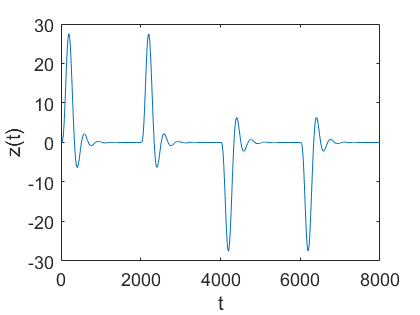

clear;
load('ctftmod.mat')
z = [dash dash dot dot];
t0 = 1:length(z);
plot(t0,z);
xlabel('t');
ylabel('z(t)');

(b)画出该滤波器的频率响应。

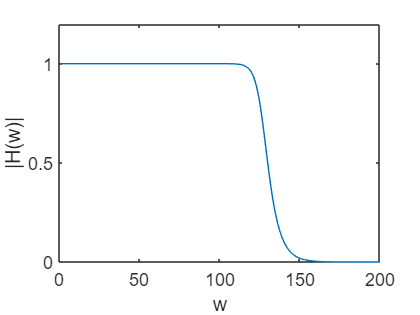

H = freqs(bf,af);
w = 1:length(H);
Hf=abs(H);  %取幅值
Hx=angle(H);  %取相位值对应相角
plot(w,Hf);
xlabel('w');
ylabel('|H(w)|');

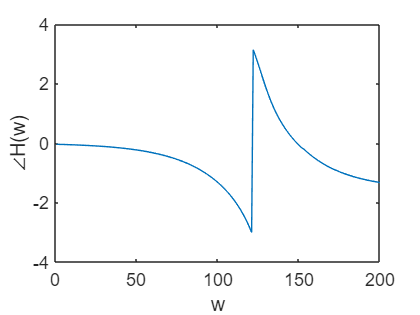

plot(w,Hx);
xlabel('w');
ylabel('∠H(w)');

(c)用lsim说明dot和dash的傅里叶变换都大致位于该低通滤波器的带宽之内

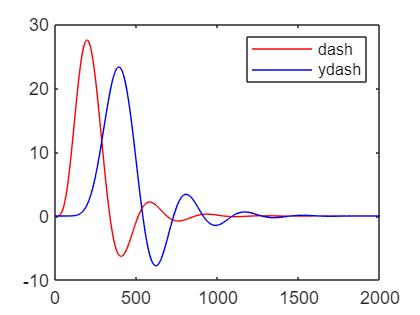

ydash = lsim(bf,af,dash,t(1:length(dash)));
ydot = lsim(bf,af,dot,t(1:length(dot)));
figure;
%画出dash和ydash的图像
plot(1:length(dash),dash,'r');
hold on
plot(1:length(dash),ydash,'b');
legend('dash','ydash');
hold off

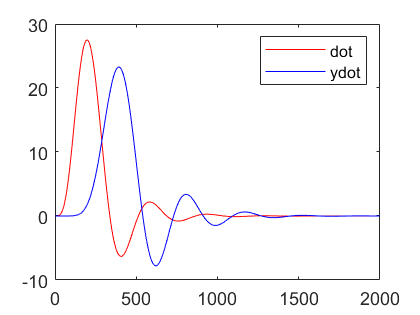

%画出dot和ydot的图像
figure;
plot(1:length(dash),dash,'r');
hold on
plot(1:length(dash),ydash,'b');
legend('dot','ydot');
hold off

结论：ydot、ydash与dot、dash相同，dot和dash的傅里叶变换都位于该低通滤波器的带宽之内。

(d)用cos(2pift)调制dash，并观察其通过滤波器后的信号图像。

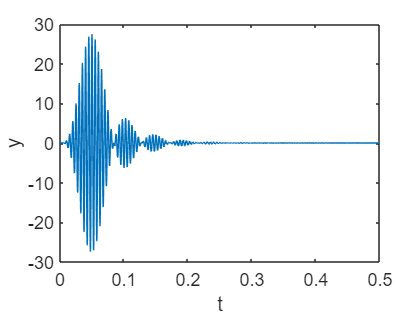

y = dash.*cos(2*pi*f1*t(1:length(dash)));
yo = lsim(bf,af,y,t(1:length(y )) );
figure;
plot(t(1:length(y )),y );
ylabel('y'),xlabel('t')

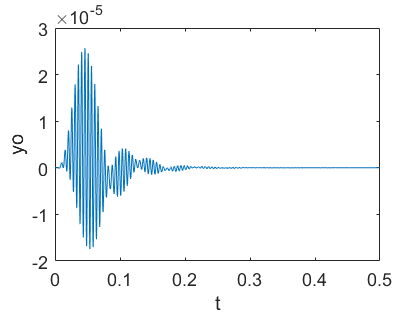

plot(t(1:length(yo)),yo);
ylabel('yo'),xlabel('t')

结论：通过滤波器的信号幅度下降较大，与猜测一致。

(e)求出题中所示三个信号的傅里叶变换。

结论：

           Y1(jw) = $\frac{1}{4}M\left(j\omega -4\pi jf_1 \right)+\frac{1}{2}M\left(j\omega \right)+\frac{1}{4}M\left(j\omega +4\pi jf_1 \right)$

           Y2(jw) = $\frac{1}{4j}M\left(j\omega -4\pi jf_1 \right)-\frac{1}{4j}M\left(j\omega +4\pi jf_1 \right)$

           Y3(jw) = $\frac{1}{4}M\left(j\omega -2\pi jf_1 -2\pi jf_2 \right)+\frac{1}{4}M\left(j\omega -2\pi jf_1 +2\pi jf_2 \right)+\frac{1}{4}M\left(j\omega +2\pi jf_1 -2\pi jf_2 \right)+\frac{1}{4}M\left(j\omega +2\pi jf_1 +2\pi jf_2 \right)$

           Y4(jw) =  $-\frac{1}{4}M\left(j\omega -4\pi jf_1 \right)+\frac{1}{2}M\left(j\omega \right)+\frac{1}{4}M\left(j\omega +4\pi jf_1 \right)$

(f)  由e可知，m(t)*cos*cos傅里叶变换为高频与二分之一原低频信号的叠加，m(t)*sin*sin为高频信号叠加，因此用cos信号调制x信号，再用低频滤波器过滤便可得m1(t)信号的二分之一。

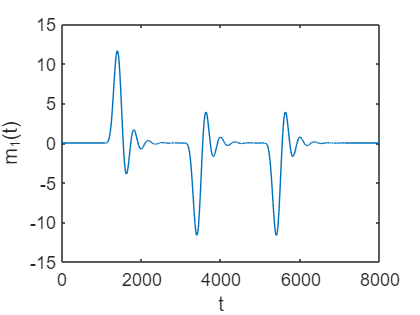

x1 = x .* cos(2*pi*f1*t(1:length(x)));
m1 = lsim(bf,af,x1,t(1:length(x1)));
plot(1:length(m1),m1);
ylabel('m_1(t)'),xlabel('t');

结论：由图可知，m1(t)为[dash dot dot]，因此为‘B’。

(g)对m2(t),m3(t)重复f过程。

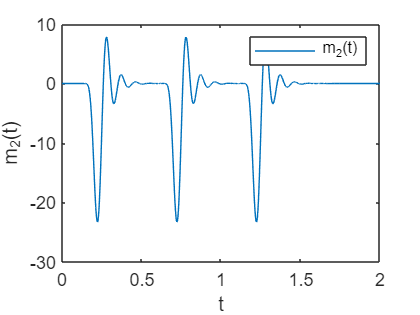

%% m_2(t)
x2 = x .* sin(2 * pi * f2 * t);
m2 = 2 * lsim(bf, af, x2, t);

plot(t, m2), xlabel("t"), ylabel("m_2(t)");
legend("m_2(t)");

结论：为‘···’，即‘S'。

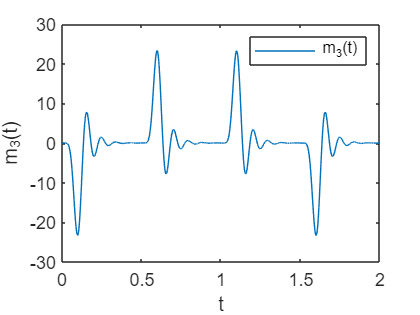

%% m_3(t)
x3 = x .* sin(2 * pi * f1 * t);
m3 = 2 * lsim(bf, af, x3, t);

plot(t, m3), xlabel("t"), ylabel("m_3(t)");
legend("m_3(t)");

结论：为’·--·‘，即’P'。

技术的未来在“DSP”。